# Entrauschen von Bildern mit einem optimalen Tiefpass

In dieser Übung wurde ein Tiefpass generiert um Bilder zu entrauschen. Man verwendet einen Tiefpass anstatt der Mittelung weil wenn man einen echtzeit Videostream zum Beispiel hat kann man nicht über 30 Bilder mitteln und zum Schluss nur das gemittelte Bild ausgeben, dies würde sich bei einem Videostream gewaltig auf die FPS(Frames per second) auswirken. Wenn man z.B. mit 60FPS einen Videostream aufnehmen würde und jeweils 30 Bilder mitteln würde dann hätte man 2 Bilder in der Sekunde als Endergebnis. Um eine echtzeit Entrauschung zu gewährleisten wird ein Tiefpass verwendet mit dem man das Rauschen aus jedem Bild herausfiltert, so bleiben bei einer Echtzeitübertragung mit 60FPS auch alle 60 Bilder erhalten.

## Einlesen der Bilder aus dem Bilderordner "LenaPics"

In dem unteren Codeblock wurden alle Bilder in dem Pfad "./LenaPics/*.jpg" eingelesen.

listdir = dir('./LenaPics/*.jpg');
N = length(listdir);
mI = zeros(512,512,N);
for x = 1:N
    path = sprintf('./LenaPics/%s', listdir(x).name);%Einlesen der Bilder
    mI(:, :, x) = imread(path);%Speichern der Bilder in einer Matrix
end

## Berechnen der Signal-to-Noise Ratio für die gemittelten Bilder

Die SN-Ratio ist ein Maß für die Qualität eines Signales, das von einem Rauschsignal überlagert ist. Die Bilder welche gemittelt werden sind auch vom Rauschen betroffen. Mit der Funktion calcSNR() werden alle Bilder gemittelt und dann das SNR in Dezibell berechnet. Das SNR nimmt mit der Anzahl der BIlder ab. Je mehr Bilder man hat desto näher kommt man an das Originalbild dran. Hätte man unendlich verrauschte Bilder und würde diese mitteln und dann die SNR berechnen würde man 1 erhalten, dies würde bedeuten das das gemittelte Bild dem originalem unverrauschten Bild entsprechen würde.

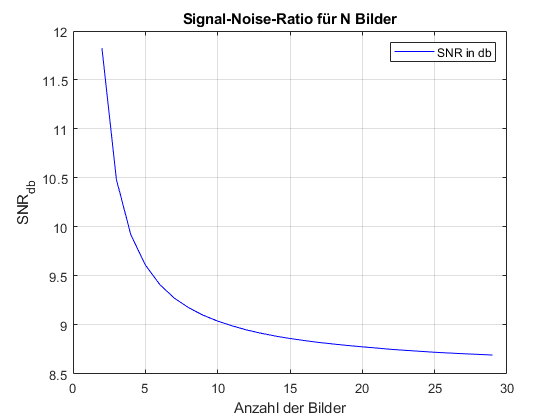

mSNR_db = zeros(N,1);
for x= 1:N
    [P_S, P_N, SNR_db, mMean, mNoise] = calcSNR(mI(:,:,1:x));%Berechnen der Signal-Noise-Ratio für 1:x Bilder
    mSNR_db(x) = SNR_db;
end
mNoise_best = mNoise;
figure,
plot(1:N, mSNR_db(:), 'b-'), grid on, legend('SNR in db'), title('Signal-Noise-Ratio für N Bilder'), xlabel('Anzahl der Bilder'), ylabel('SNR_{db}');

## Berechnen der Signal-to-Noise Ratio für Bilder die mittels Tiefpass entrauscht wurden

Um einen Tiefpass für die Entrauschung von Bildern zu dimensionieren wird der Wert des SNR dem Signal-Noise-Distortion-Ratio gegenübergestellt. Der SDR gibt die Qualität des Signals an. Je höher der Wert desto besser ist die Qualität des Bildes/Signals. Um einen optimalen Filter zu bekommen wird der Sigma-Wert des Hochpunkts von SDR in Dezibell ermittel und dann für den besseren Filter verwendet. 

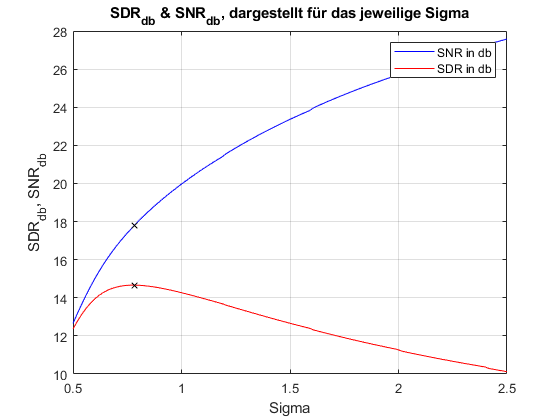

vSNR_db = [];
mI_best = mMean;%Seperates speichern des besten Bildes(gemitteltes Bild)
vSDR_db = [];
vSigma = linspace(0.5, 2.5, 100);%Generieren der 100 Sigma Werte von 0,5 bis 2,5 
for sigma = vSigma
    L = 2 * ceil(5/2 * sigma)+1;
    mH_Gaus = fspecial('gaussian', L, sigma);
    
    mI_filterd = imfilter(mI, mH_Gaus);
    
    [P_S, P_N, SNR_db, mMean, mNoise] = calcSNR(mI_filterd);
    vSNR_db(end+1) = SNR_db;
    
    mD = mI_filterd - mI_best;
    P_D = std(mD(:)).^2;
    SDR = P_S / P_D;
    
    vSDR_db(end+1) = 10*log10(SDR);
    
end

maximum = max(vSDR_db);
[y, x] = find(vSDR_db==maximum);
figure,
plot(vSigma, vSNR_db, 'b-', vSigma, vSDR_db, 'r-',vSigma(x), maximum, 'kx', vSigma(x), vSNR_db(x), 'kx'),grid on, legend('SNR in db', 'SDR in db'), xlabel('Sigma'), ylabel('SDR_{db}, SNR_{db}'), title('SDR_{db} & SNR_{db}, dargestellt für das jeweilige Sigma');

## Rauschfilterung mit dem optimalen Tiefpasssfilter

Die optimalen Werte für den Tiefpassfilter, welche vorhin ermittelt wurden, werden jetzt in den neuen Filter eingesetzt. Das Bild hat mit dem neuen Filter das optimale Verhältnis zwischen Rauschen und Qualität. Die Filterung mit dem Tiefpass ist zwar nicht so gut wie die Filterung mittel Mittelung ist aber besser geeignet für echtzeit Anwendungen wie z. B. einem Videostream.

L_opt = 2 * ceil(5/2*vSigma(x))+1;
mH_Gaus_opt = fspecial('gaussian', L_opt, vSigma(x));
mI_filterd_opt = imfilter(mI(:,:,1), mH_Gaus_opt);

## Gegenüberstellung: Entrauschte Bilder mittels Mittelung/Tiefpassfilterung

In der unteren Figure kann man den Unterschied zwischen der Filterung mittels Mittlerung und mittels Tiefpass gut erkennen. Bei dem Bild nach der Tiefpassfilterung kann man noch ein leichtes Rauschen erkennen, bei dem Bild nach der Mittelung nicht.

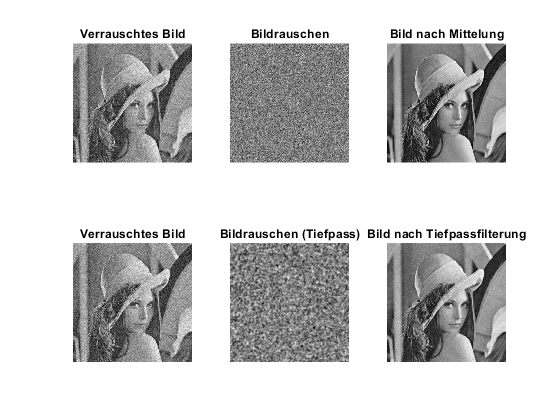

figure,
subplot(231), imshow(mI(:,:,1), []), title('Verrauschtes Bild'),
subplot(232), imshow(mNoise_best(:,:,1), []), title('Bildrauschen'),
subplot(233), imshow(mI_best, []), title('Bild nach Mittelung'),
subplot(234), imshow(mI(:,:,1), []), title('Verrauschtes Bild')
subplot(235), imshow(mNoise(:,:,1), []), title('Bildrauschen (Tiefpass)')
subplot(236), imshow(mI_filterd_opt, []), title('Bild nach Tiefpassfilterung')